# Optimization of PID parameters for robot control position

#### Instrucciones

- **Definir los valores de posicion de referencia deseada para el robot. Ejecutar el siguiente codigo y luego ejecutar el modelo simunlink *****cst_robotarm_optimized.slx***

joint1_ctrl = 60;
joint2_ctrl = 140;
joint3_ctrl = 70;
joint4_ctrl = 50;
joint5_ctrl = 60;
joint6_ctrl = 40;


        2. **Caso contrario, continuar con la ejecucion secuencial del resto de codigo para la optimizacion por partes.**

### Motor 1

#### Open-loop response: Motor 1

% Create plant
K=13.86;
T=0.0002648;
plant = tf(K,[T 1 0]);

%figure("Name","Open-loop Step Response for system");
%step(plant,0:0.05:t_max);

#### Closed-loop response: Motor 1

% Differential Evolution initial parameters
config = struct();
config.populationSize = 20;
config.maxIterations = 20;
config.F = 0.7;
config.CR = 0.5;
config.maxPIDValue = 1;% At initialization

joint1_ctrl = 60;
joint2_ctrl = 0;
joint3_ctrl = 0;
joint4_ctrl = 0;
joint5_ctrl = 0;
joint6_ctrl = 0;

% PID otimization
Solution_m1 = Control_PID_adapted(plant,config,"motor 1")

% PID parameters 
% bestmem: [3.3180 0.1642 0.1163]
% error: 0.3370

### Motor 2

#### Open-loop response: Motor 2

% Create plant
K=32.8;
T=0.2307;
plant = tf(K,[T 1 0]);

% figure("Name","Open-loop Step Response for system");
% step(plant,0:0.05:t_max);

#### Closed-loop response: Motor 2

Iteration: 5
Best Error: 0.2946 | Worst Error: 0.3858 | Global Error: 6.7746
PID Parameters - Kp: 9.9682 | Ki: 1.6730 | Kd: 3.3581

Iteration: 10
Best Error: 0.2261 | Worst Error: 0.2929 | Global Error: 5.1926
PID Parameters - Kp: 10.1484 | Ki: 10.5105 | Kd: 0.4994

Iteration: 15
Best Error: 0.1897 | Worst Error: 0.2242 | Global Error: 4.1028
PID Parameters - Kp: 15.8923 | Ki: 19.9820 | Kd: 0.2057

Iteration: 20
Best Error: 0.1802 | Worst Error: 0.1972 | Global Error: 3.7800
PID Parameters - Kp: 17.9852 | Ki: 20.5596 | Kd: 0.0000



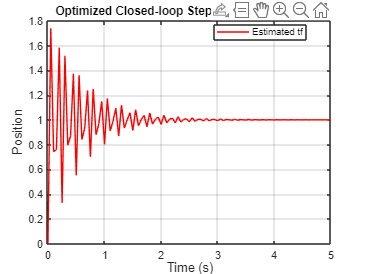

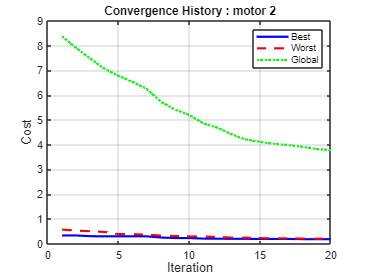

Solutionv1_2 = struct with fields:
       bestmem: [17.9852 20.5596 0]
         error: 0.1802
    population: [20×4 double]
          CONV: [1×1 struct]
             M: [1×1 tf]

config.populationSize = 20;
config.maxIterations = 20;
config.F = 0.7;
config.CR = 1;
config.maxPIDValue = 5;% At initialization 

joint1_ctrl = 60;
joint2_ctrl = 140;
joint3_ctrl = 0;
joint4_ctrl = 0;
joint5_ctrl = 0;
joint6_ctrl = 0;

% PID otimization
Solution_m2 = Control_PID2(plant,config,": motor 2")

% PID parameters 
% bestmem: [17.7028 18.4274 0.0104]
% error: 0.1964

### Motor 3

#### Open-loop response: Motor 3

% Create plant
K=29.85;
T=0.001451;
plant = tf(K,[T 1 0]);

% figure("Name","Open-loop Step Response for system");
% step(plant,0:0.05:t_max);

#### Closed-loop response: Motor 3

Iteration: 5
Best Error: 0.3384 | Worst Error: 0.4221 | Global Error: 7.3942
PID Parameters - Kp: 9.6609 | Ki: 10.8598 | Kd: 0.6054

Iteration: 10
Best Error: 0.3357 | Worst Error: 0.3588 | Global Error: 6.8237
PID Parameters - Kp: 9.8366 | Ki: 9.9739 | Kd: 0.8896

Iteration: 15
Best Error: 0.3279 | Worst Error: 0.3382 | Global Error: 6.7004
PID Parameters - Kp: 9.3406 | Ki: 14.0338 | Kd: 0.6717

Iteration: 20
Best Error: 0.3151 | Worst Error: 0.3323 | Global Error: 6.4796
PID Parameters - Kp: 9.2812 | Ki: 16.0853 | Kd: 0.7250

Iteration: 25
Best Error: 0.3116 | Worst Error: 0.3195 | Global Error: 6.2989
PID Parameters - Kp: 9.3956 | Ki: 17.2427 | Kd: 0.5501

Iteration: 30
Best Error: 0.3076 | Worst Error: 0.3112 | Global Error: 6.1981
PID Parameters - Kp: 9.1803 | Ki: 18.8143 | Kd: 0.3100



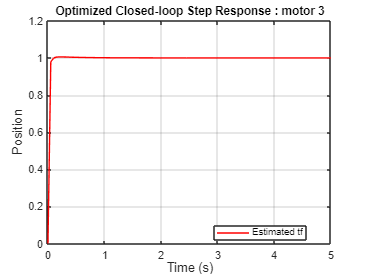

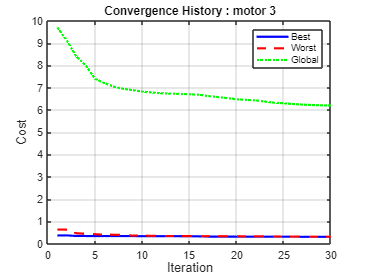

Solutionv1_2 = struct with fields:
       bestmem: [9.1803 18.8143 0.3100]
         error: 0.3076
    population: [20×4 double]
          CONV: [1×1 struct]
             M: [1×1 tf]

% Differential Evolution initial parameters
config = struct();
config.populationSize = 20;
config.maxIterations = 40;
config.F = 0.5;
config.CR = 0.5;
config.maxPIDValue = 6;% At initialization

joint1_ctrl = 60;
joint2_ctrl = 140;
joint3_ctrl = 70;
joint4_ctrl = 0;
joint5_ctrl = 0;
joint6_ctrl = 0;

% PID otimization
Solution_m3 = Control_PID2(plant,config,": motor 3")


% Iteration: 5
% Best Error: 0.3445 | Worst Error: 0.4558 | Global Error: 8.2098
% PID Parameters - Kp: 6.8227 | Ki: 9.2459 | Kd: 0.3407
% 
% Iteration: 10
% Best Error: 0.3219 | Worst Error: 0.3886 | Global Error: 6.9475
% PID Parameters - Kp: 7.5710 | Ki: 14.1220 | Kd: 0.0000
% 
% Iteration: 15
% Best Error: 0.2715 | Worst Error: 0.3271 | Global Error: 6.0359
% PID Parameters - Kp: 11.6785 | Ki: 37.8982 | Kd: 0.1216
% 
% Iteration: 20
% Best Error: 0.2350 | Worst Error: 0.2985 | Global Error: 5.2691
% PID Parameters - Kp: 15.6143 | Ki: 72.1112 | Kd: 0.0851

% PID parameters 
% bestmem: [9.2892 16.8208 0.0153]
% error: 0.3054

### Motor 4

#### Open-loop response: Motor 4

% Create plant
% Identificando: q4 [0 : -50]
K=-10.06;
T=0.3432;
plant = tf(K,[T 1 0]);

% Identificando: q4 [0 : 50]
% K=14.5;
% T=0.04741;
% plant = tf(K,[T 1 0]);

% figure("Name","Open-loop Step Response for system");
% step(plant,0:0.05:t_max);

#### Closed-loop response: Motor 4

Iteration: 5
Best Error: 0.1888 | Worst Error: 0.2986 | Global Error: 4.9986
PID Parameters - Kp: 9.3185 | Ki: 5.0614 | Kd: 0.5549

Iteration: 10
Best Error: 0.1544 | Worst Error: 0.2141 | Global Error: 3.5961
PID Parameters - Kp: 13.9861 | Ki: 2.7681 | Kd: 0.0000

Iteration: 15
Best Error: 0.1449 | Worst Error: 0.1543 | Global Error: 2.9932
PID Parameters - Kp: 18.7335 | Ki: 5.9502 | Kd: 0.0426

Iteration: 20
Best Error: 0.1445 | Worst Error: 0.1468 | Global Error: 2.9093
PID Parameters - Kp: 28.6230 | Ki: 11.6376 | Kd: 0.0637



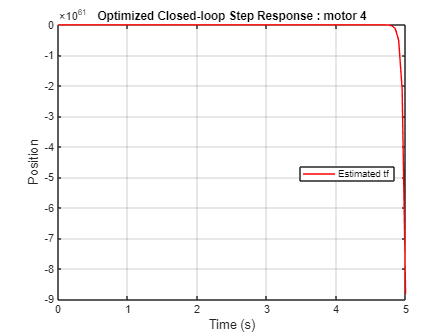

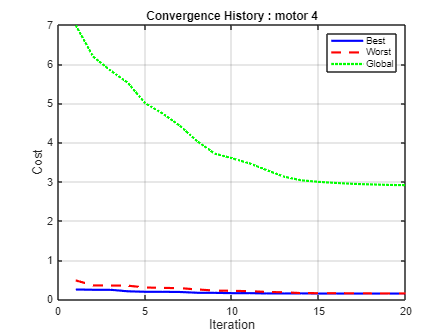

Solutionv1_2 = struct with fields:
       bestmem: [28.6230 11.6376 0.0637]
         error: 0.1445
    population: [20×4 double]
          CONV: [1×1 struct]
             M: [1×1 tf]

% Differential Evolution initial parameters
config = struct();
config.populationSize = 20;
config.maxIterations = 20;
config.F = 0.5;
config.CR = 0.5;
config.maxPIDValue = 6;% At initialization

joint1_ctrl = 60;
joint2_ctrl = 140;
joint3_ctrl = 70;
joint4_ctrl = 50;
joint5_ctrl = 0;
joint6_ctrl = 0;

% PID otimization
Solution_m4 = Control_PID2(plant,config,": motor 4")

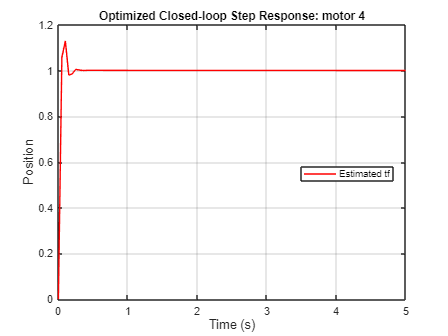

% PID parameters
% bestmem: [28.6230 11.6376 0.0637]
% error: 0.1445

### Motor 5

#### Open-loop response: Motor 5

% Create plant
% Identificando: q5 [0 : 60]
K=14.02;
T=0.0003768;
plant = tf(K,[T 1 0]);

% figure("Name","Open-loop Step Response for system");
% step(plant,0:0.05:t_max);

#### Closed-loop response: Motor 5

Iteration: 5
Best Error: 0.1904 | Worst Error: 0.2908 | Global Error: 4.9838
PID Parameters - Kp: 9.4372 | Ki: 1.0222 | Kd: 0.0000

Iteration: 10
Best Error: 0.1834 | Worst Error: 0.1976 | Global Error: 3.7634
PID Parameters - Kp: 10.2720 | Ki: 0.0000 | Kd: 0.0000

Iteration: 15
Best Error: 0.1792 | Worst Error: 0.1838 | Global Error: 3.6258
PID Parameters - Kp: 11.4137 | Ki: 0.0851 | Kd: 0.0000

Iteration: 20
Best Error: 0.1758 | Worst Error: 0.1791 | Global Error: 3.5558
PID Parameters - Kp: 12.3126 | Ki: 0.1702 | Kd: 0.0000



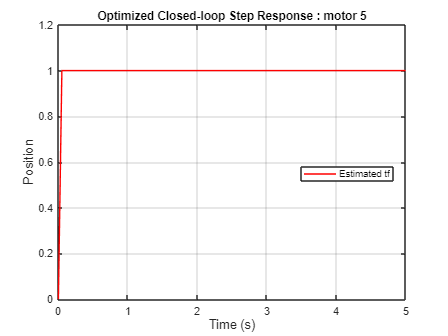

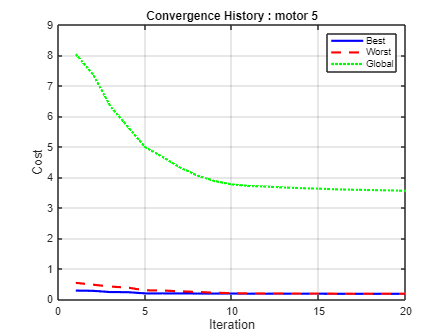

Solutionv1_2 = struct with fields:
       bestmem: [12.3126 0.1702 0]
         error: 0.1758
    population: [20×4 double]
          CONV: [1×1 struct]
             M: [1×1 tf]

% Differential Evolution initial parameters
config = struct();
config.populationSize = 20;
config.maxIterations = 20;
config.F = 0.5;
config.CR = 0.5;
config.maxPIDValue = 6;% At initialization

joint1_ctrl = 60;
joint2_ctrl = 140;
joint3_ctrl = 70;
joint4_ctrl = 50;
joint5_ctrl = 60;
joint6_ctrl = 0;

% PID otimization
Solution_m5 = Control_PID2(plant,config,": motor 5")

% PID parameters 
%bestmem: [12.3126 0.1702 0]
%error: 0.1758

### Open-loop response: Motor 6

% Create plant
% Identificando: q5 [0 : 60]
K=9.31;
T=0.001593;
plant = tf(K,[T 1 0]);

% figure("Name","Open-loop Step Response for system");
% step(plant,0:0.05:t_max);

### Closed-loop response: Motor 6

Iteration: 5
Best Error: 0.1686 | Worst Error: 0.2299 | Global Error: 3.9006
PID Parameters - Kp: 8.0811 | Ki: 1.3381 | Kd: 1.2314

Iteration: 10
Best Error: 0.1182 | Worst Error: 0.1673 | Global Error: 2.7050
PID Parameters - Kp: 10.6305 | Ki: 0.9076 | Kd: 0.0000

Iteration: 15
Best Error: 0.1009 | Worst Error: 0.1175 | Global Error: 2.1837
PID Parameters - Kp: 12.5610 | Ki: 0.0000 | Kd: 0.0000

Iteration: 20
Best Error: 0.0969 | Worst Error: 0.1030 | Global Error: 2.0065
PID Parameters - Kp: 14.2833 | Ki: 0.0000 | Kd: 0.0000



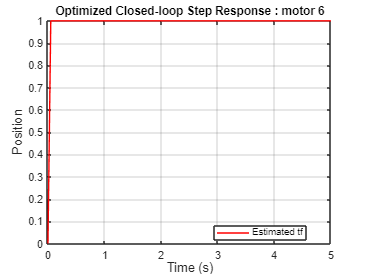

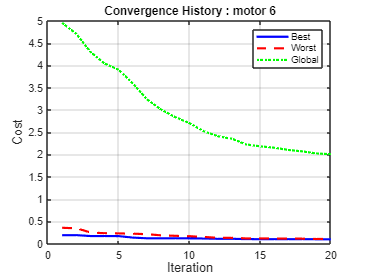

Solutionv1_2 = struct with fields:
       bestmem: [14.2833 0 0]
         error: 0.0969
    population: [20×4 double]
          CONV: [1×1 struct]
             M: [1×1 tf]

% Differential Evolution initial parameters
config = struct();
config.populationSize = 20;
config.maxIterations = 20;
config.F = 0.5;
config.CR = 0.5;
config.maxPIDValue = 6;% At initialization

joint1_ctrl = 60;
joint2_ctrl = 140;
joint3_ctrl = 70;
joint4_ctrl = 50;
joint5_ctrl = 60;
joint6_ctrl = 40;

% PID otimization
Solution_m6 = Control_PID2(plant,config,": motor 6")

% PID parameters 
% bestmem: [14.2833 0 0]
% error: 0.0969

# Graficar salidas desde Simulink de forma personalizada

Exportar **robot_respuesta_control_opt** desde el modelo Simulink con Simulation Data Expector

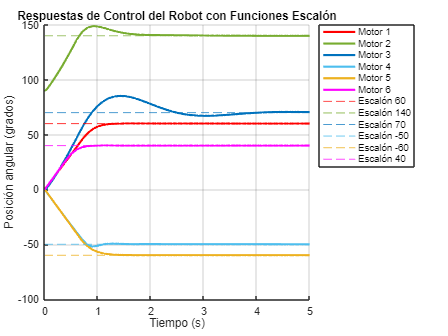

% Initial data
%t_max = 5; % Tiempo máximo de simulacion
%time = 0:0.05:t_max;

% Configuración de la figura
figure;
hold on;

% Conversión de radianes a grados
conv_factor = 180 / pi;
data1 = robot_respuesta_control_opt{1}.Values.Data * conv_factor;
data2 = robot_respuesta_control_opt{2}.Values.Data * conv_factor;
data3 = robot_respuesta_control_opt{3}.Values.Data * conv_factor;
data4 = robot_respuesta_control_opt{4}.Values.Data * conv_factor;
data5 = robot_respuesta_control_opt{5}.Values.Data * conv_factor;
data6 = robot_respuesta_control_opt{6}.Values.Data * conv_factor;

% Valores de tiempo
time = robot_respuesta_control_opt{1}.Values.Time;

% Gráficos de las respuestas de control
plot(time, data1, 'r', 'DisplayName', 'Motor 1','LineWidth',2);
plot(time, data2, 'Color', [0.4660 0.6740 0.1880], 'DisplayName', 'Motor 2','LineWidth',2);
plot(time, data3, 'Color', [0 0.4470 0.7410], 'DisplayName', 'Motor 3','LineWidth',2);
plot(time, data4, 'Color', [0.3010 0.7450 0.9330], 'DisplayName', 'Motor 4','LineWidth',2);
plot(time, data5, 'Color', [0.9290 0.6940 0.1250], 'DisplayName', 'Motor 5','LineWidth',2);
plot(time, data6, 'm', 'DisplayName', 'Motor 6','LineWidth',2);

% Funciones escalón
yline(60, '--r', 'DisplayName', 'Escalón 60','LineWidth',1);
yline(140, '--', 'Color', [0.4660 0.6740 0.1880],'DisplayName', 'Escalón 140','LineWidth',1);
yline(70, '--', 'Color', [0 0.4470 0.7410], 'DisplayName', 'Escalón 70','LineWidth',1);
yline(-50, '--', 'Color', [0.3010 0.7450 0.9330], 'DisplayName', 'Escalón -50','LineWidth',1);
yline(-60, '--', 'Color', [0.9290 0.6940 0.1250],'DisplayName', 'Escalón -60','LineWidth',1);
yline(40, '--m', 'DisplayName', 'Escalón 40','LineWidth',1);

% Etiquetas y título
xlabel('Tiempo (s)');
ylabel('Posición angular (grados)');
title('Respuestas de Control del Robot con Funciones Escalón');

% Leyenda
legend('Location','bestoutside')

% Mostrar cuadrícula
grid on;

hold off;